clc;
clear;

syms t a
assume(a > 0);
assume(t > 0);

## 阿基米德螺旋线

阿基米德螺旋线的参数方程为：

x=a*t*cos(t);
y=a*t*sin(t);

其中 t 为转过的弧度。

令 a = 1，画出阿基米德螺旋线

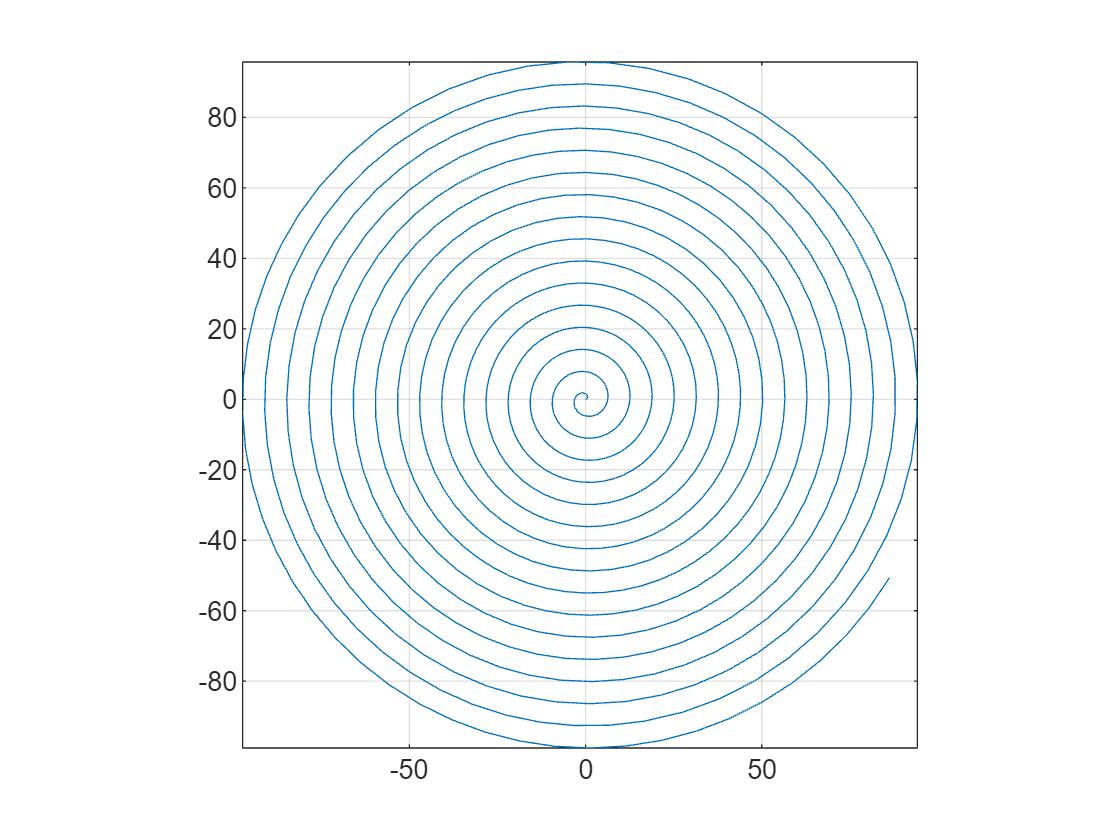

fplot(subs(x,a,1),subs(y,a,1),[0,100]);
axis equal;
grid on;

## 用曲线积分计算阿基米德螺旋线的弧长

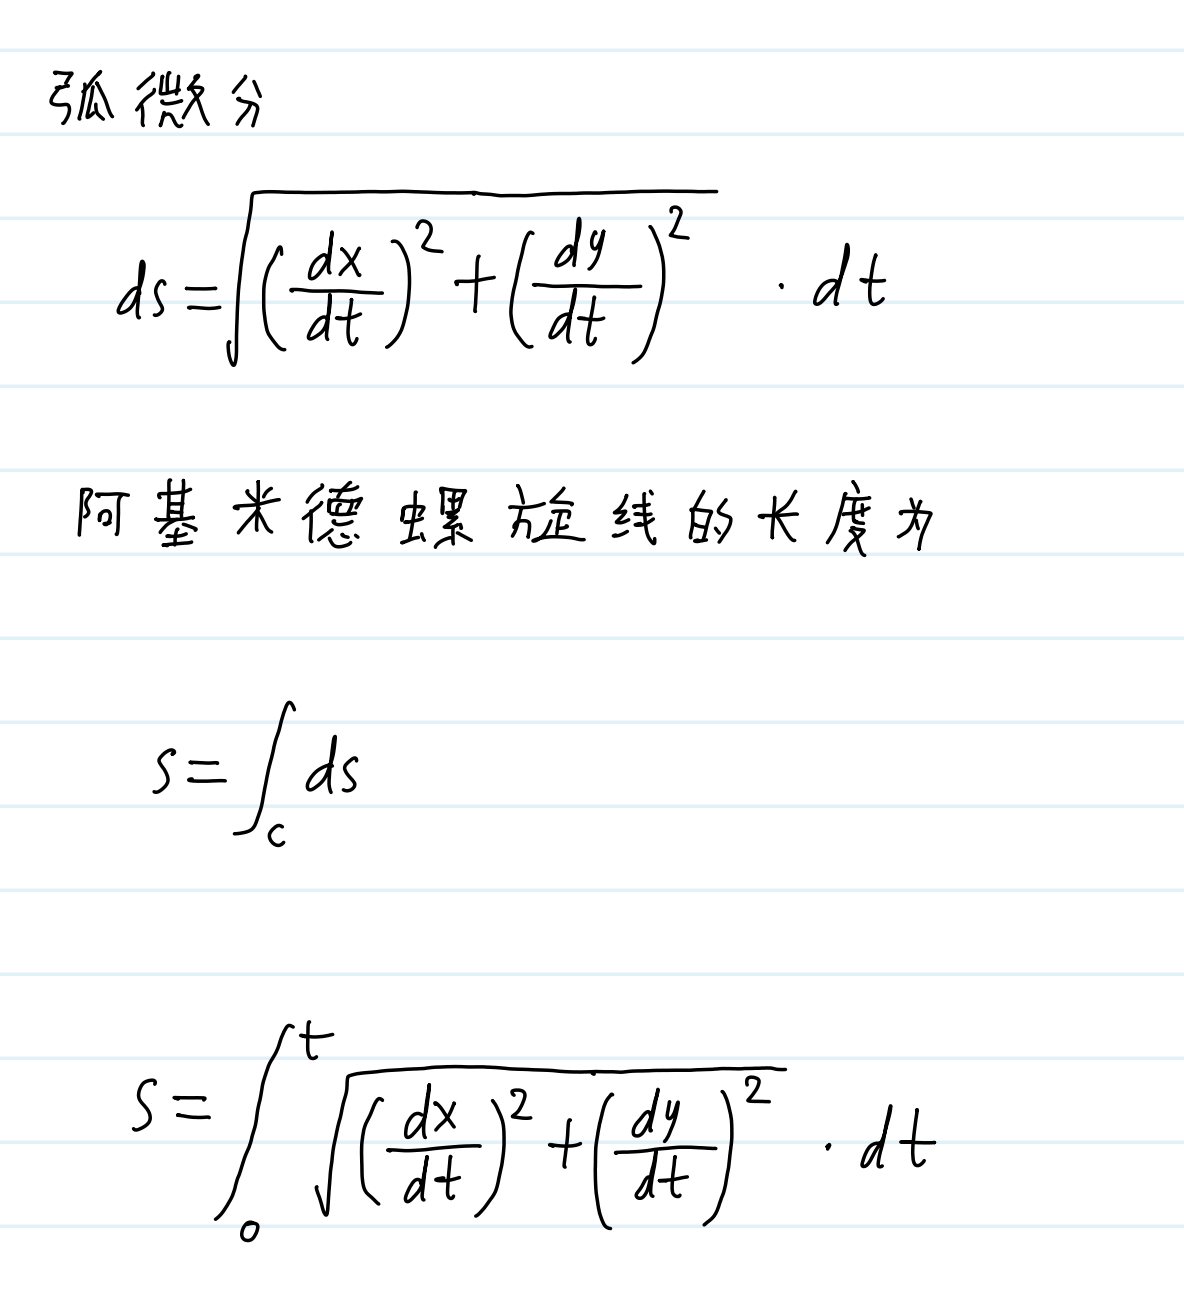

使用 matlab 进行计算

s=int(sqrt(diff(x,t)^2+diff(y,t)^2),t,0,t);
s=simplify(s)

$$s = a\,\int_{0}^{t}\sqrt{t^{2}+1}\mathrm{d}t$$

此时 matlab 给出的结果中含有积分，通过 subs 函数，将 a 换成 a (实际上等于没有替换)，matlab 会将积分算出来，而不是直接呈现一个积分号在那。

s=subs(s,a,a)

$$s = a\,\left(\frac{\mathrm{asinh}\left(t\right)}{2}+\frac{t\,\sqrt{t^{2}+1}}{2}\right)$$

结果中含有 asinh 函数。我们先看一下 sinh 函数的图像

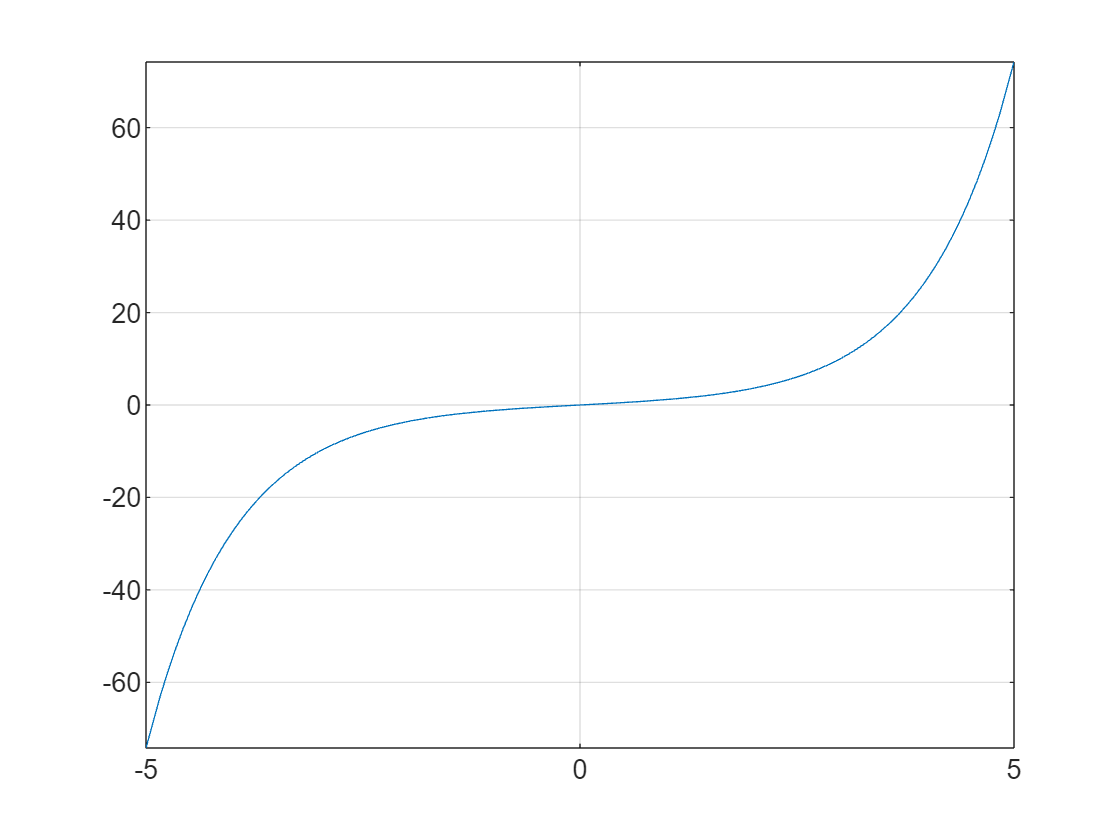

fplot(t,sinh(t));
grid on;

再看一下 asinh 函数的图像

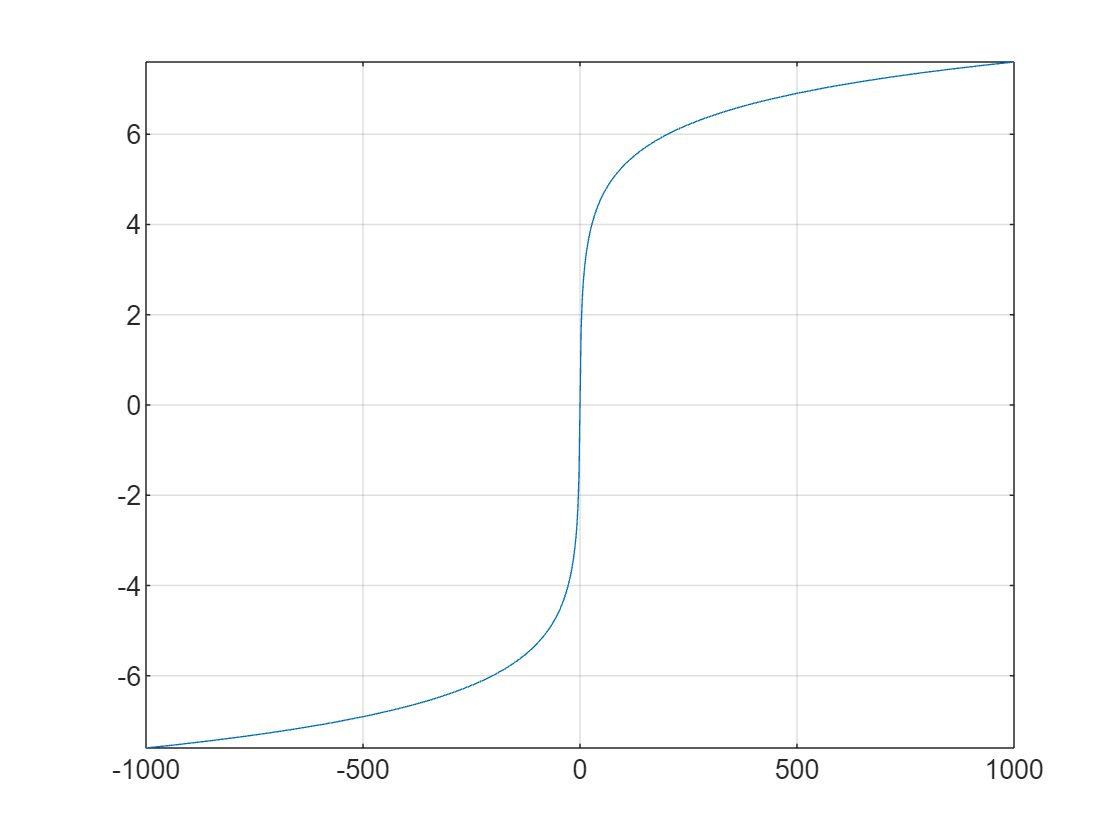

fplot(t,asinh(t),[-1000,1000]);
grid on;

可以看到 asinh 函数后期增速变慢。求一下导数看看

diff_asinh=diff(asinh(t),t)

$$diff\_asinh = \frac{1}{\sqrt{t^{2}+1}}$$

画出 diff_asinh 的图像

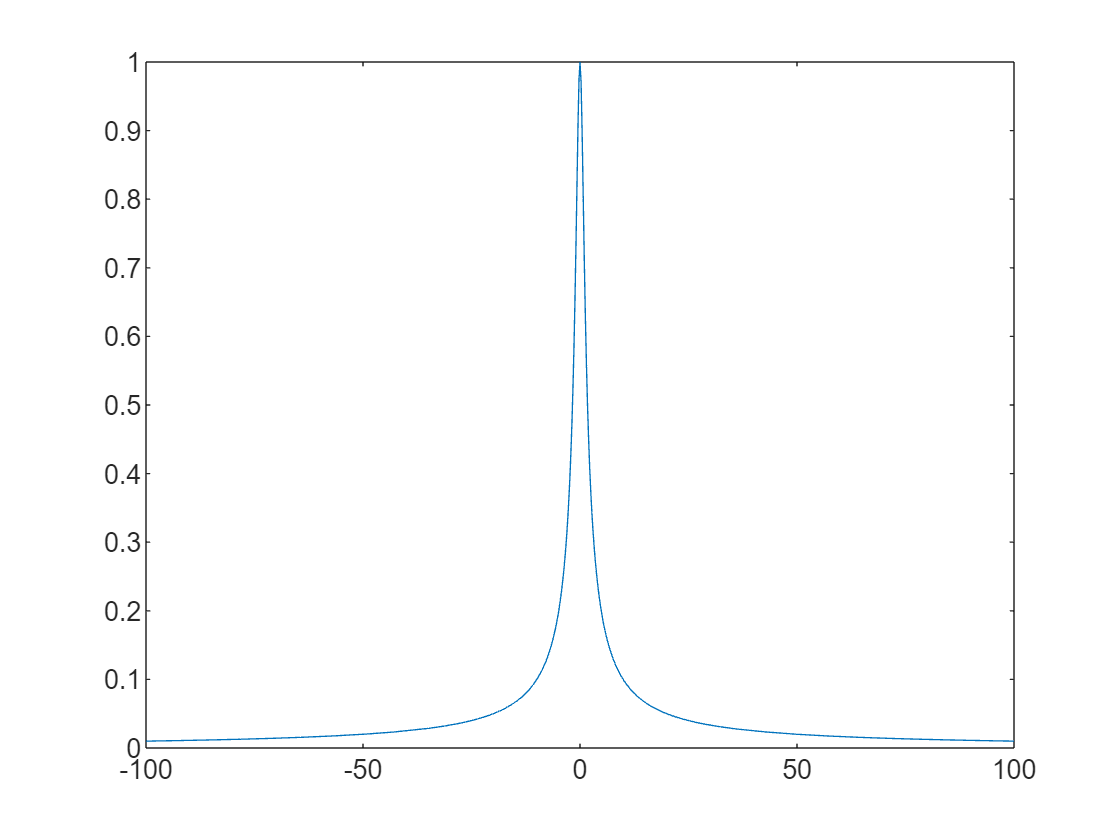

fplot(t,diff_asinh,[-100,100]);

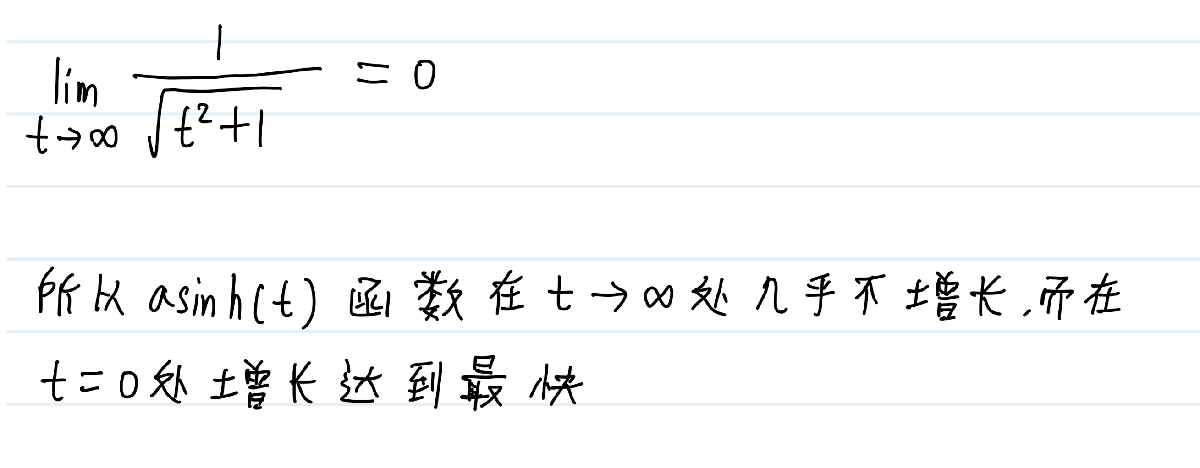

## 带入a，研究s的图像

% 看一下 a=1 , 时，s 随 t 是怎么变化的
s1=subs(s,a,1)

$$s1 = \frac{\mathrm{asinh}\left(t\right)}{2}+\frac{t\,\sqrt{t^{2}+1}}{2}$$

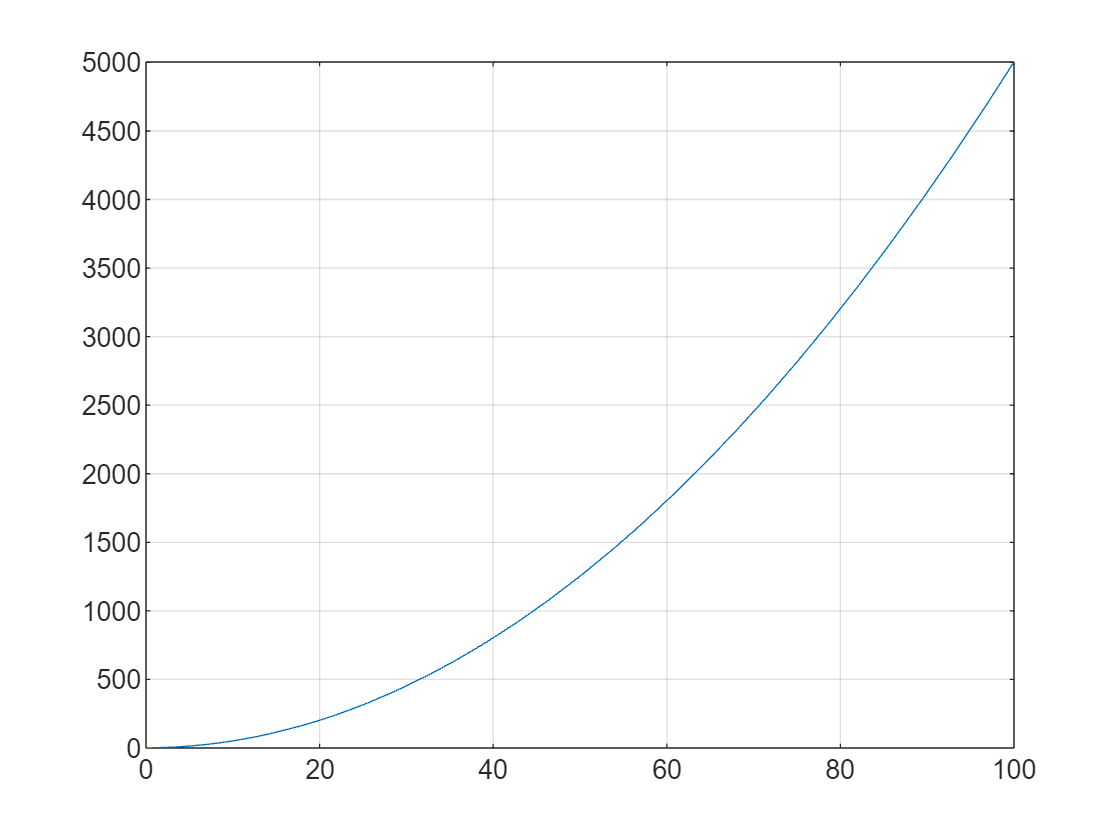

fplot(t,s1,[0,100]);
grid on

求一下导数看看

d_s1=diff(s1,t)

$$d\_s1 = \frac{1}{2\,\sqrt{t^{2}+1}}+\frac{\sqrt{t^{2}+1}}{2}+\frac{t^{2}}{2\,\sqrt{t^{2}+1}}$$

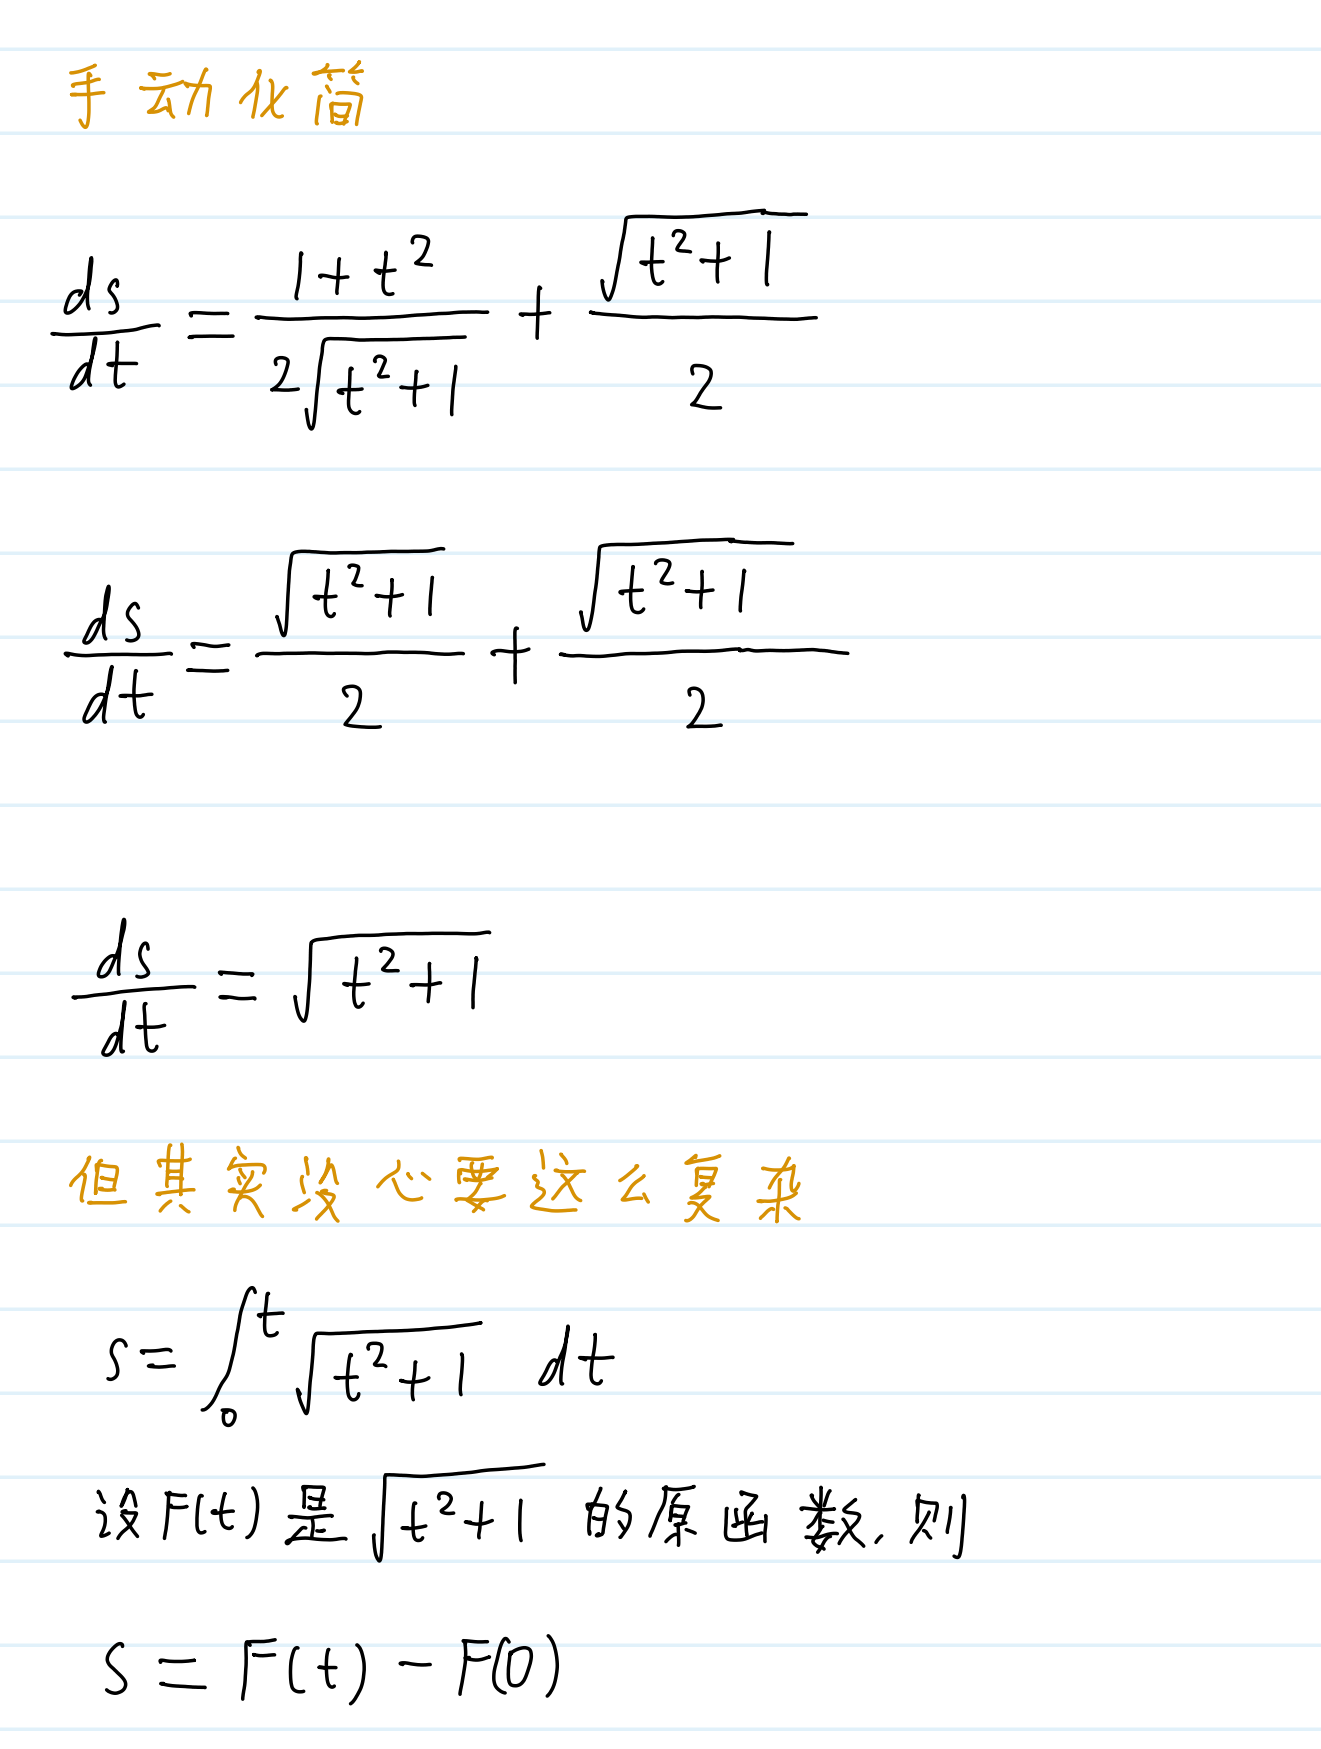

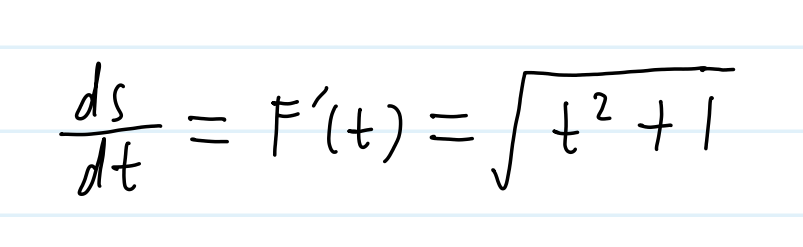

画出 d_s1 的图像

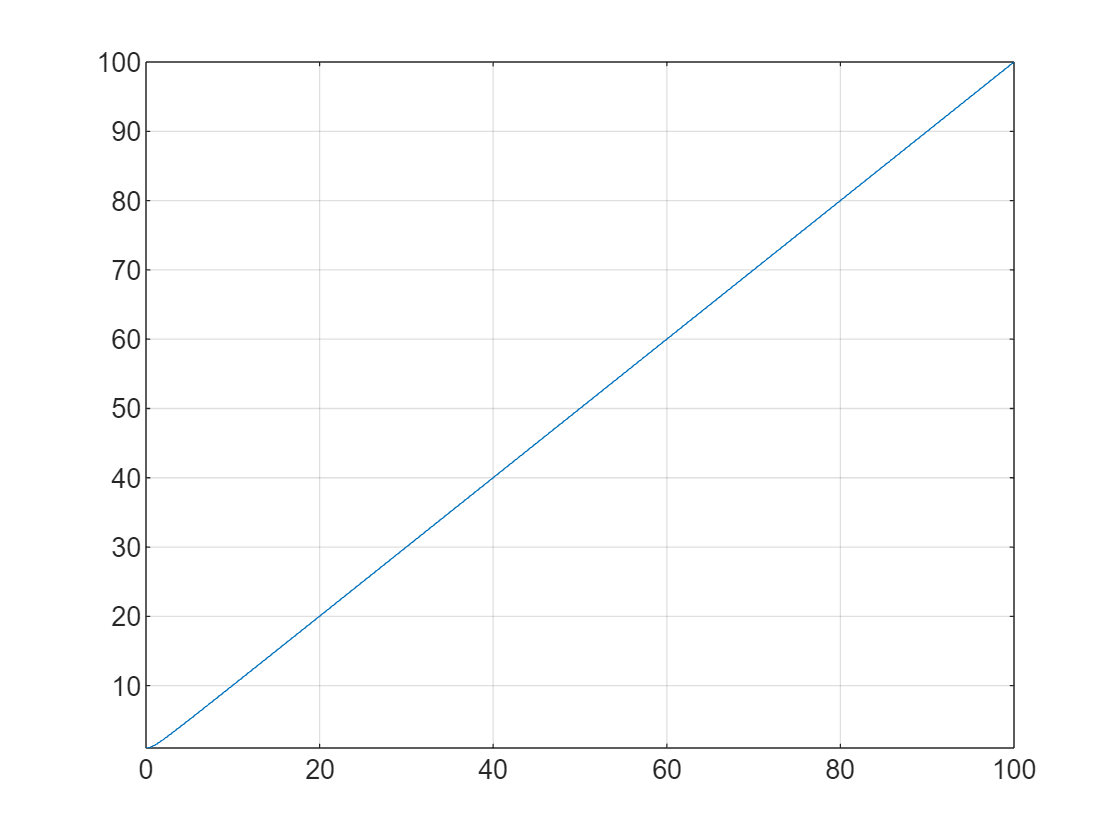

fplot(t,d_s1,[0,100]);
grid on;

可以看到几乎是一条直线。

对 d_s1 接着求导，画出曲线

dd_s1=diff(d_s1,t)

$$dd\_s1 = \frac{3\,t}{2\,\sqrt{t^{2}+1}}-\frac{t}{2\,{\left(t^{2}+1\right)}^{3/2}}-\frac{t^{3}}{2\,{\left(t^{2}+1\right)}^{3/2}}$$

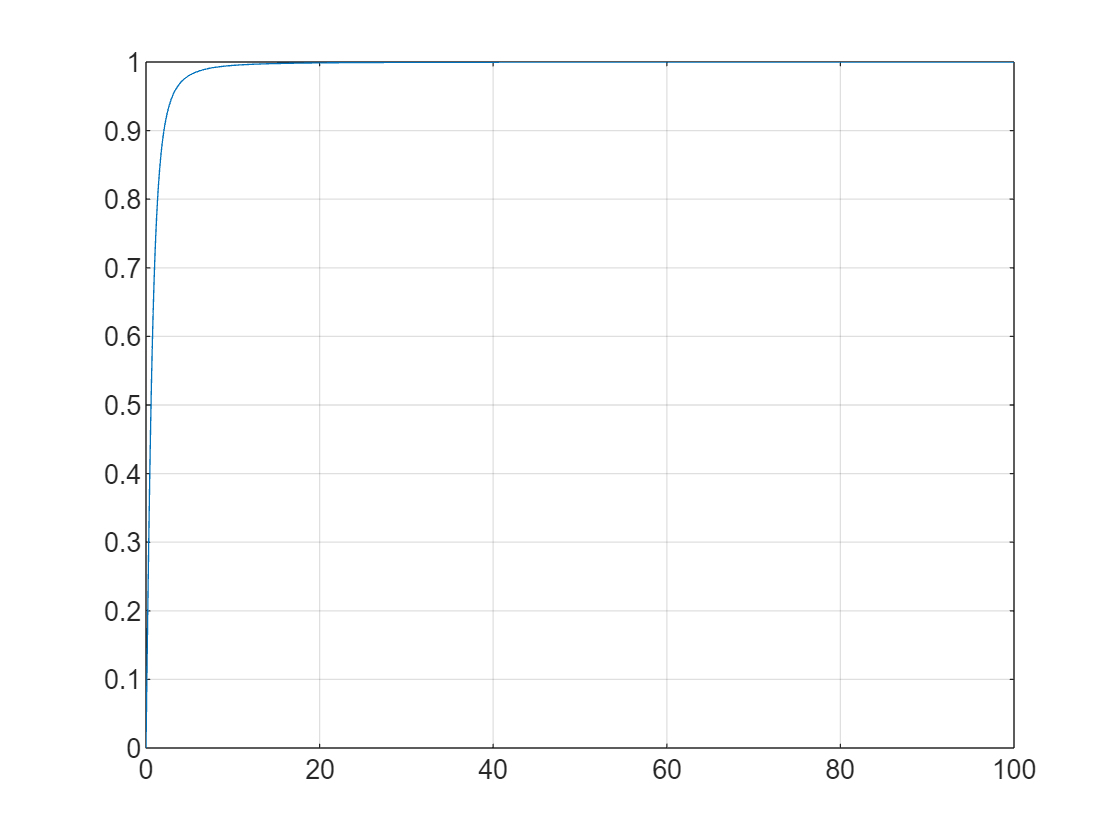

fplot(t,dd_s1,[0,100]);
grid on;

可以看到 s1 的二阶导后期几乎水平，前期上升也非常快，难怪一阶导看起来像是一条直线。

求一下二阶导的极限

lim_dd_s1=limit(dd_s1,t,inf)

$$lim\_dd\_s1 = 1$$

可以看到确实是后期趋近于水平。

## s, ds, dds

刚才是令 a=1，现在不这么做，再算一次。

s

$$s = a\,\left(\frac{\mathrm{asinh}\left(t\right)}{2}+\frac{t\,\sqrt{t^{2}+1}}{2}\right)$$

ds=diff(s,t);
[ds_num,ds_den]=numden(ds);
ds=ds_num/ds_den

$$ds = a\,\sqrt{t^{2}+1}$$

dds=diff(ds,t)

$$dds = \frac{a\,t}{\sqrt{t^{2}+1}}$$

lim_dds=limit(dds,t,inf)

$$lim\_dds = a$$

## 近似

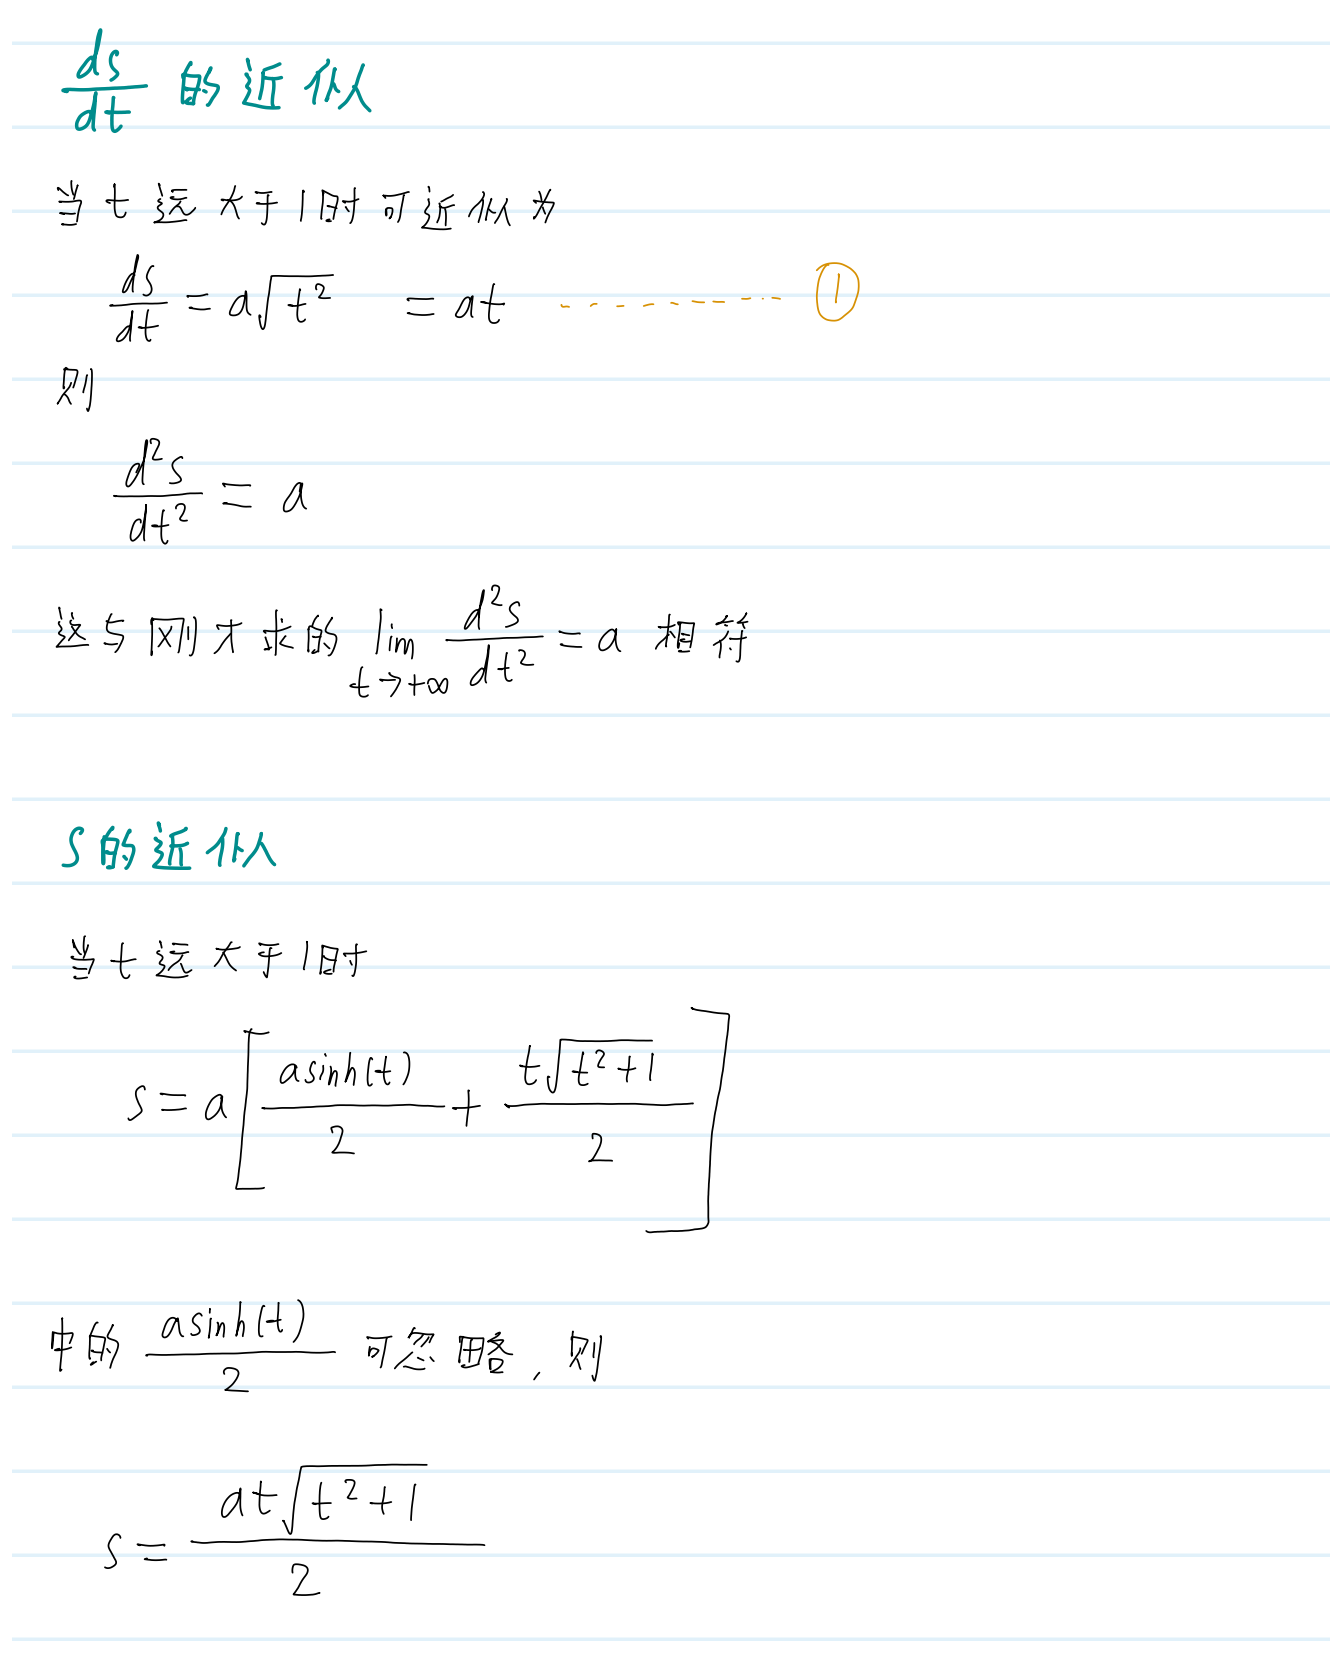

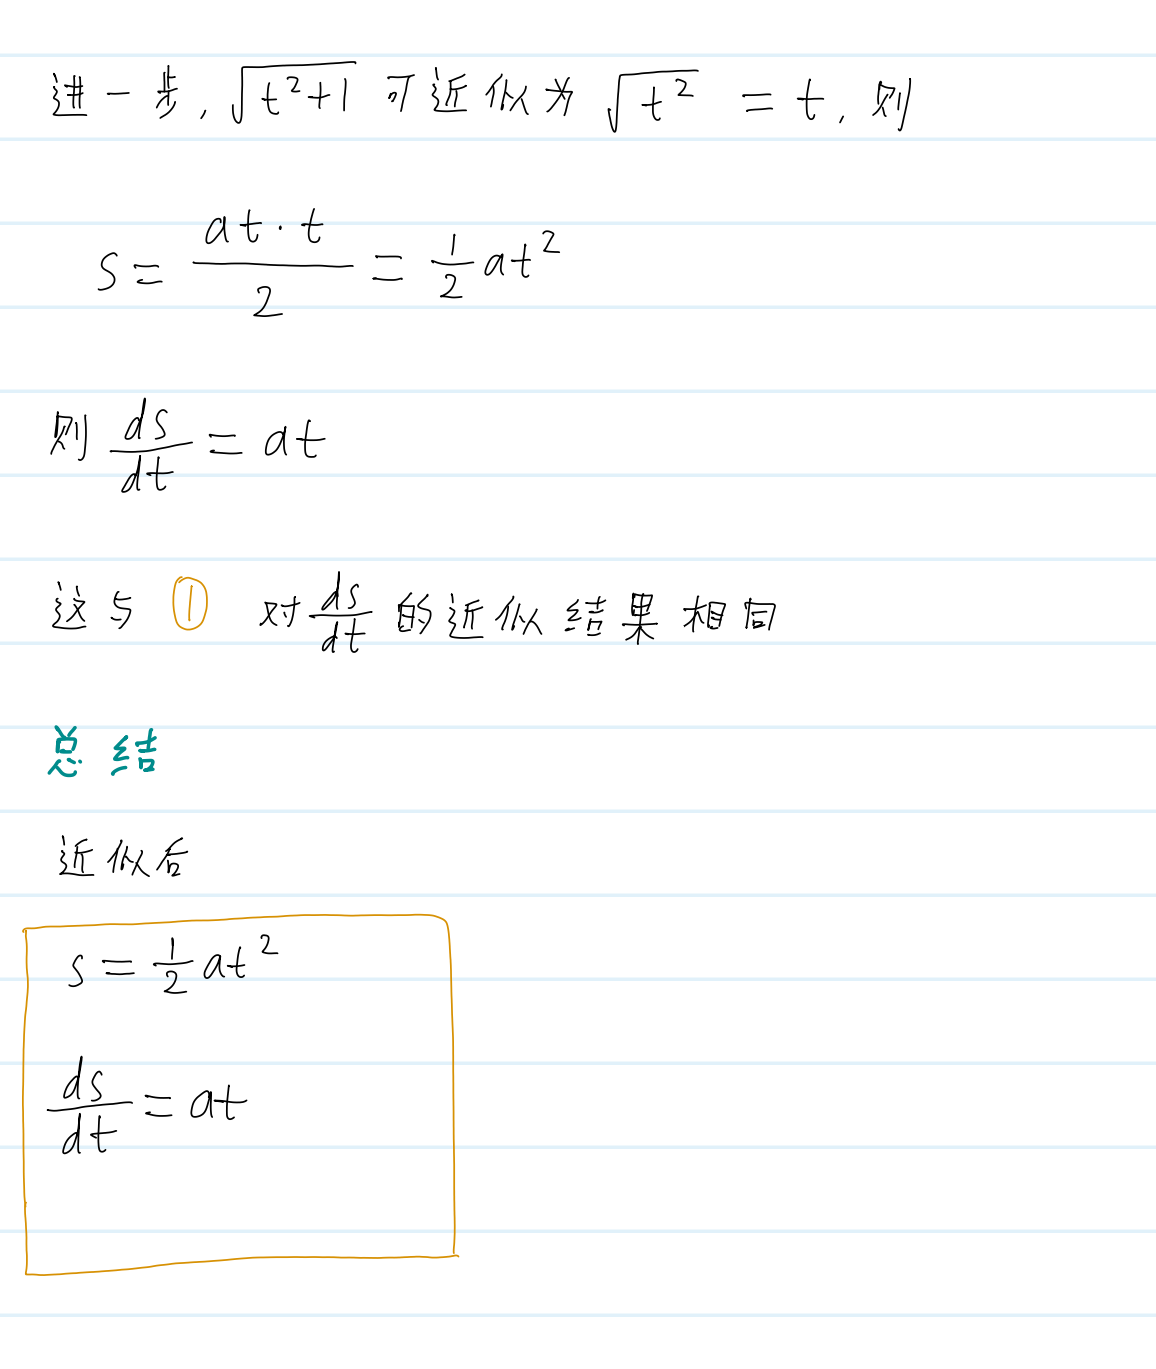

s=0.5*a*t^2

$$s = \frac{a\,t^{2}}{2}$$

ds=diff(s,t)

$$ds = a\,t$$

dds=diff(ds,t)

$$dds = a$$

## 绕线时 a 的物理意义

绕线时，线一圈一圈盘起来的结构符合阿基米德螺旋线。经典的例子有蚊香和大大卷。如下图：

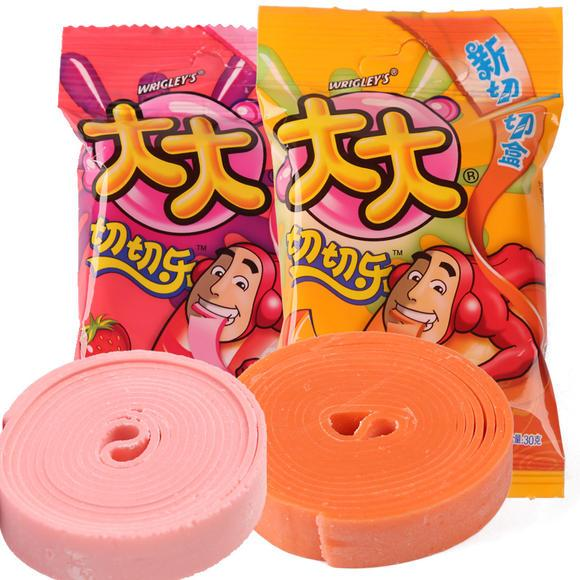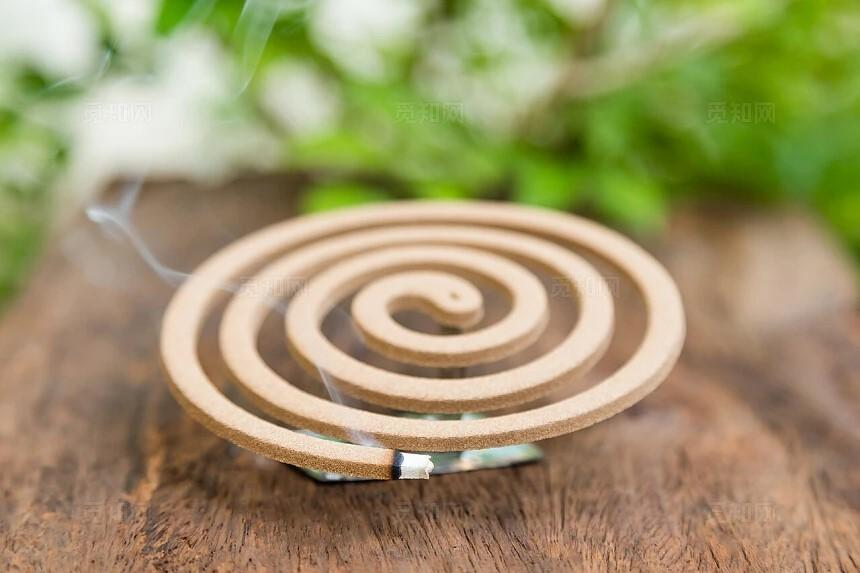

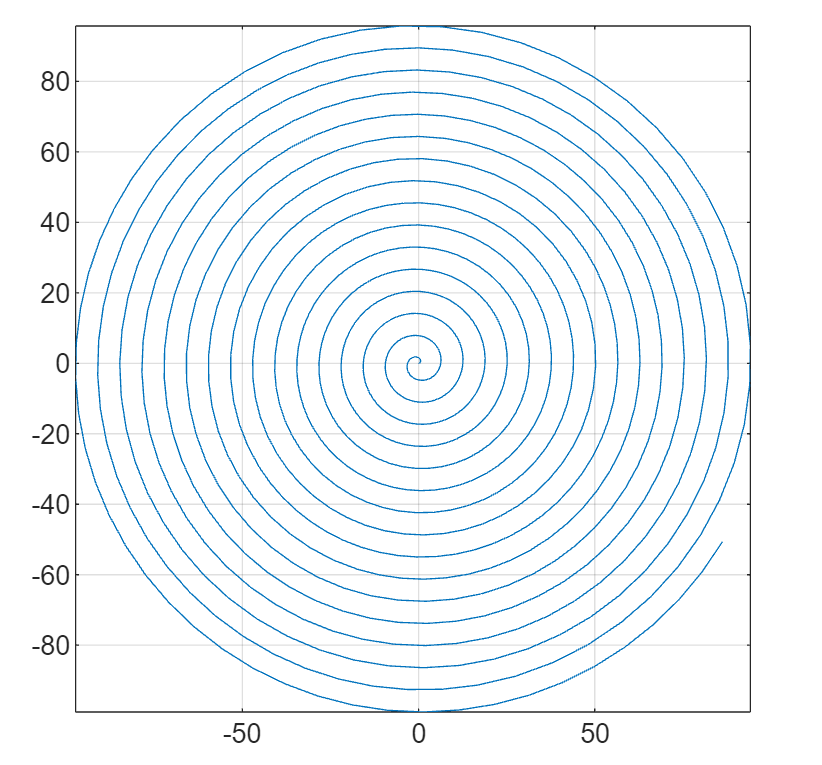

阿基米德螺旋线中 a 的物理意义是曲线上的点离开原点的速度。绕线时，一圈紧贴着一圈。当绕了一圈后，线上的点离开原点的距离就等于线宽。设线宽为 D。

syms D

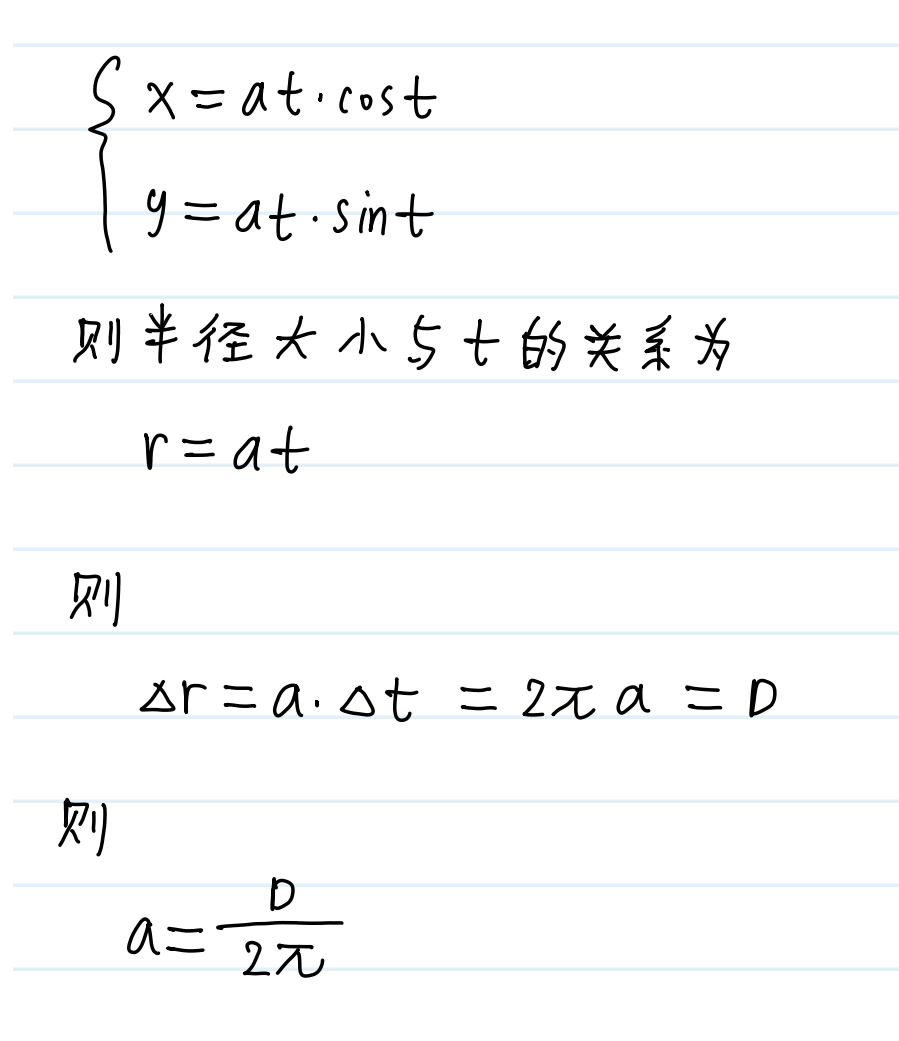

s=subs(s,a,D/(2*pi))

$$s = \frac{\text{D}\,t^{2}}{4\,\pi }$$

ds=diff(s,t)

$$ds = \frac{\text{D}\,t}{2\,\pi }$$

dds=diff(ds,t)

$$dds = \frac{\text{D}}{2\,\pi }$$

## 再转一圈的 Δs

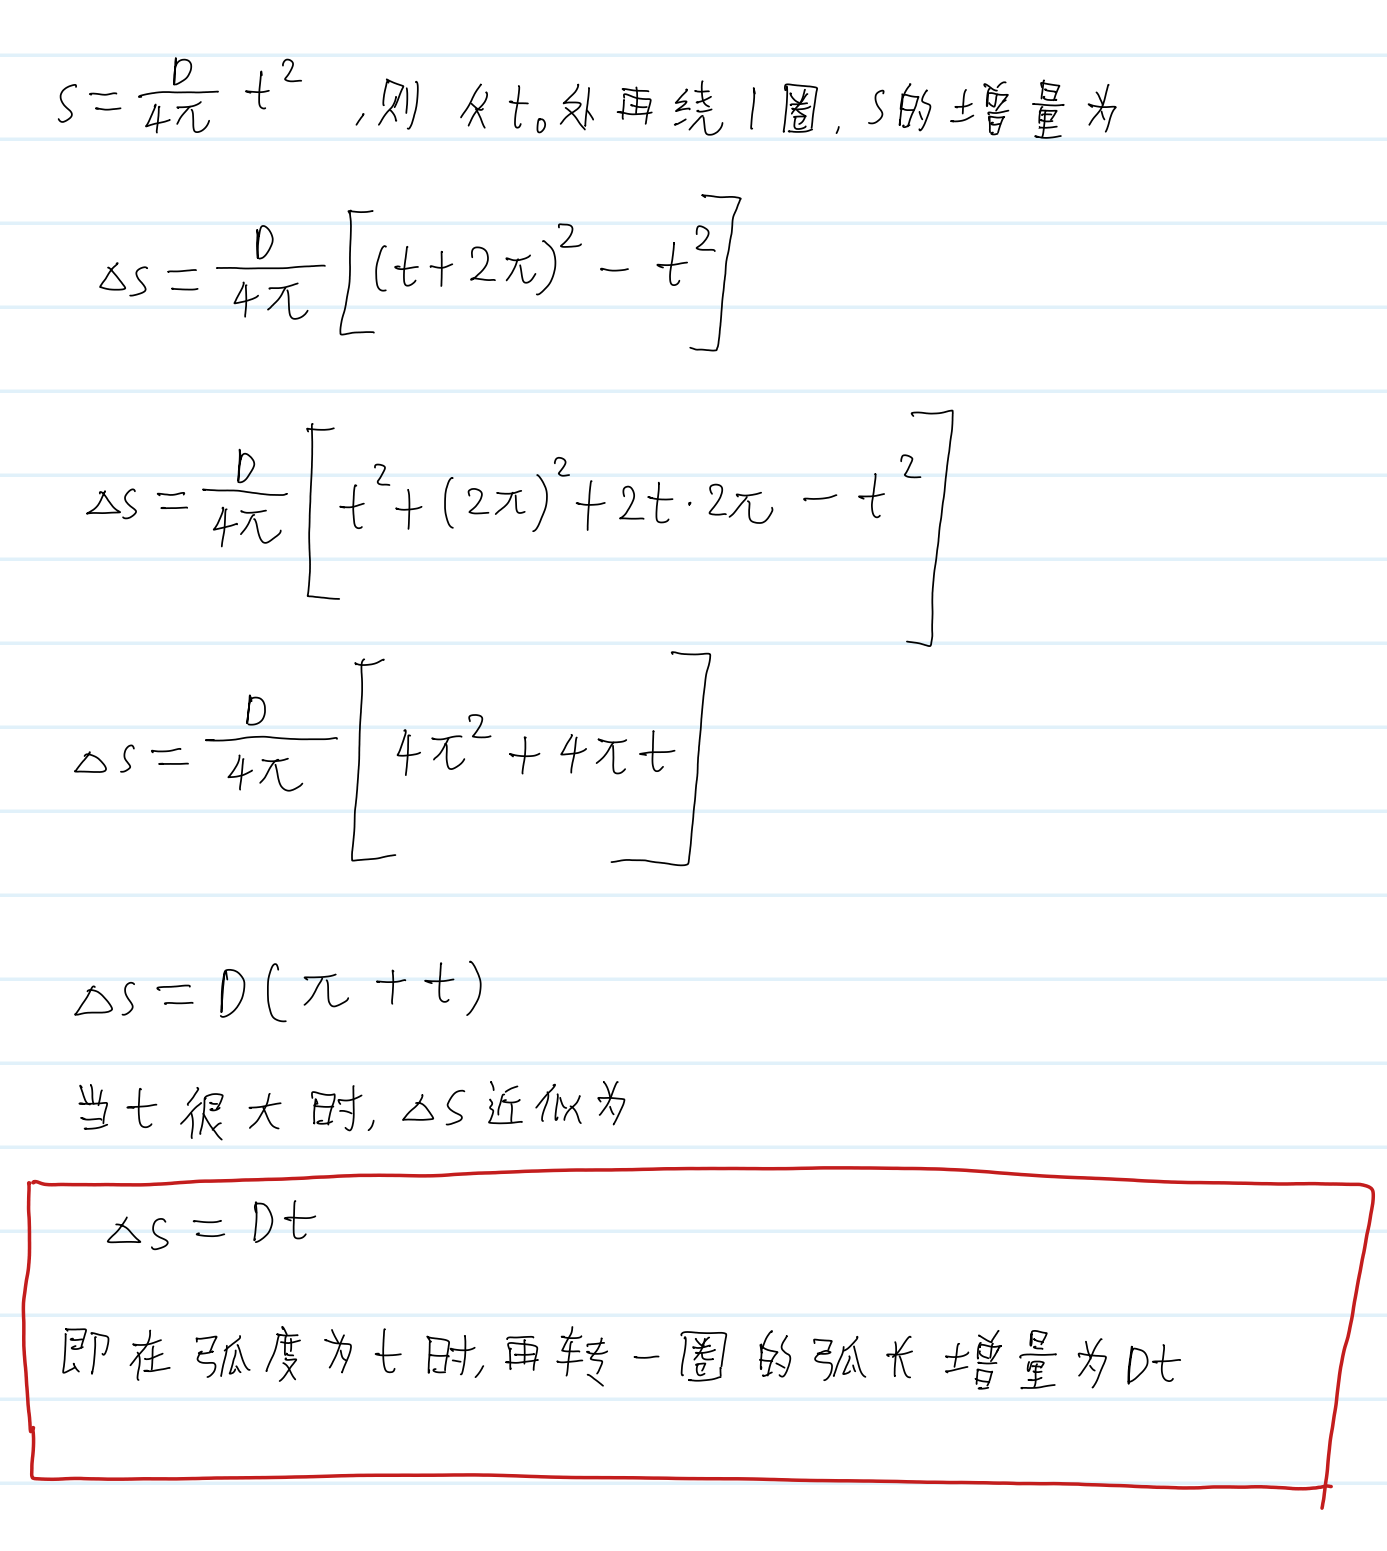

## 收放卷

空卷半径为 r0

满卷半径为 r1

总圈数为 N

syms r0 r1 N
% 每收一圈半径增大一个 D，则
equ=r0+N*D==r1

$$equ = r_{0}+\text{D}\,N=r_{1}$$

D=solve(equ,D)

$$D = -\frac{r_{0}-r_{1}}{N}$$

每收一圈半径增大一个 D，则当前的半径为：

r=D*t/(2*pi)

$$r = -\frac{t\,\left(r_{0}-r_{1}\right)}{2\,N\,\pi }$$

设在 r0 处对应 t=t0，在 r1 处对应 t=t1

syms t0 t1
equ1=r0==subs(r,t,t0);
t0=solve(equ1,t0)

$$t0 = -\frac{2\,\pi \,N\,r_{0}}{r_{0}-r_{1}}$$

equ2=r1==subs(r,t,t1);
t1=solve(equ2,t1)

$$t1 = -\frac{2\,\pi \,N\,r_{1}}{r_{0}-r_{1}}$$

## 放卷的迭代过程

初始时 t=t1，每转一圈，t 减小 2pi，则当前的 t 为

syms n
% n 为已放出的圈数
t=t1-2*pi*n

$$t = -2\,\pi \,n-\frac{2\,\pi \,N\,r_{1}}{r_{0}-r_{1}}$$

在当前位置，再放出一圈，弧长减小

delta_s=D*t;
delta_s=simplify(delta_s)

$$delta\_s = \frac{2\,\pi \,\left(N\,r_{1}+n\,r_{0}-n\,r_{1}\right)}{N}$$

手动化简

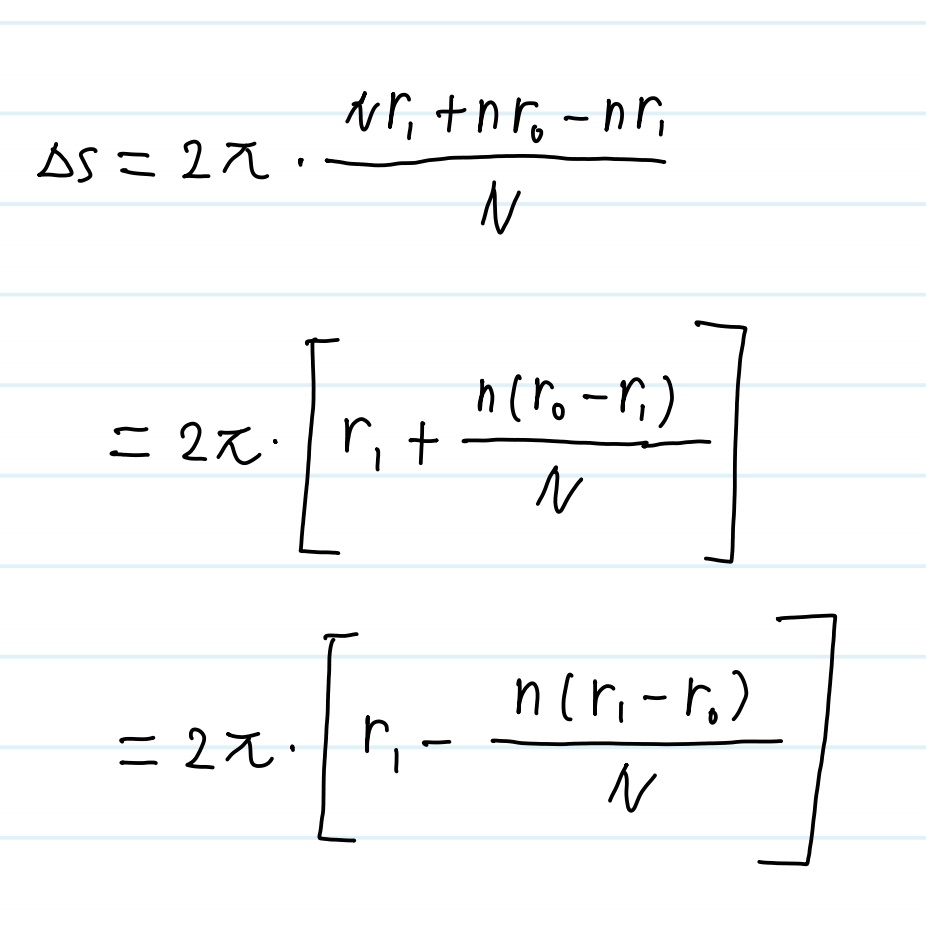

## 通俗算法